## Model/Method

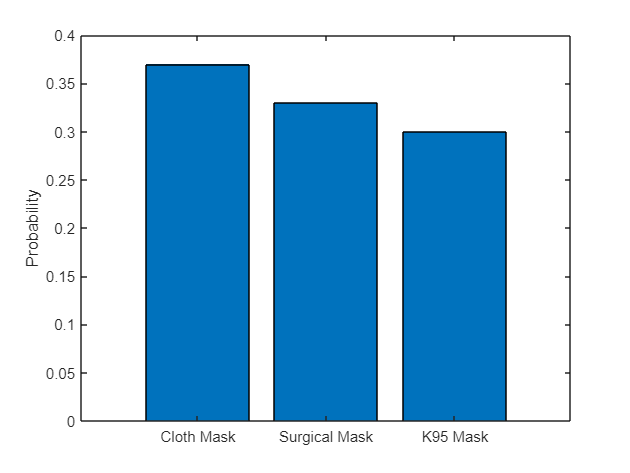

% mask efficacy
clothMaskEfficacy = .56;
surgicalMaskEfficacy = .66;
K95MaskEfficacy = .83;

% mask probability distribution (multinomial)
clothMaskProb = 0.37;
surgicalMaskProb = 0.33;
K95MaskProb = 0.3;
pd_mask_probabilities = makedist('Multinomial','Probabilities',[clothMaskProb surgicalMaskProb K95MaskProb]);

% Visualize
maskOutcomes = categorical({'Cloth Mask','Surgical Mask','K95 Mask'});
maskOutcomes = reordercats(maskOutcomes,{'Cloth Mask','Surgical Mask','K95 Mask'});
x = 1:3;
pr = pd_mask_probabilities.pdf(x);
figure();
bar(maskOutcomes, pr)
ylabel('Probability')

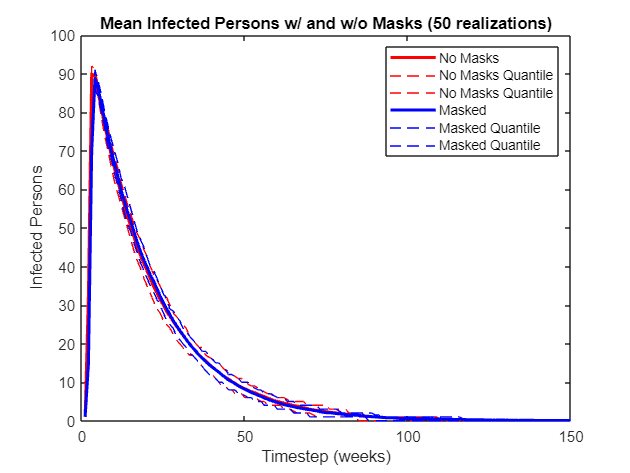

mask_matrix_random = random(pd_mask_probabilities, 100, 100);
mask_efficacy = [clothMaskEfficacy surgicalMaskEfficacy K95MaskEfficacy];
mask_matrix = mask_efficacy(mask_matrix_random); % converst from 1,2, and 3 to cloth, surgical, and K95 efficacy values (respectively)

% adjacency matrix 100 ppl
pop = 100;
no_mask_matrix = ~eye(pop,pop);

% Final Vulnerability Matrix
masked_vulnerability_matrix = no_mask_matrix - mask_matrix;
masked_vulnerability_matrix = masked_vulnerability_matrix.*-(eye(height(masked_vulnerability_matrix))-1);

% Simulate absir model w/ and w/o masks
    % Set the number of replications for the agent-based model
n_realizations = 100;
    % Run each simulation for 150 timesteps
T_simulation = 150;
    % Reserve space for simulation results
I_ensemble_no_mask = zeros(T_simulation, n_realizations);
I_ensemble_mask = zeros(T_simulation, n_realizations);
    % Set the random seed. 
rng(101)
    % Set parameter values
infection_rate = .5;
recovery_rate = 0.05;

    % Generate the sample of results
for i = 1 : n_realizations
    % Run a single simulation
    Iv1 = zeros(pop, 1);
    Iv1(1) = 1;
    [Sh_mask, Ih_mask, Rh_mask] = simulate_absir(masked_vulnerability_matrix, Iv1, T_simulation, infection_rate, recovery_rate);
    [Sh_no_mask, Ih_no_mask, Rh_no_mask] = simulate_absir(no_mask_matrix, Iv1, T_simulation, infection_rate, recovery_rate);
    % Summarize and store the infection history
    I_ensemble_mask(:, i) = sum(Ih_mask, 1);
    I_ensemble_no_mask(:, i) = sum(Ih_no_mask, 1);
end

    % Compute the mean and quantiles
    % Masked
I_mean_mask = mean(I_ensemble_mask, 2); % mean
I_lo_mask = quantile(I_ensemble_mask, 0.25, 2); % Lower (25%) quantile
I_up_mask = quantile(I_ensemble_mask, 0.75, 2); % Upper (75%) quantile
    % No mask
I_mean_no_mask = mean(I_ensemble_no_mask, 2);
I_lo_no_mask = quantile(I_ensemble_no_mask, 0.25, 2);
I_up_no_mask = quantile(I_ensemble_no_mask, 0.75, 2);

    % Visualize
figure()
% plot w/o masks
plot(I_mean_no_mask, 'r-', 'LineWidth', 2.0, 'DisplayName', 'No Masks'); hold on
plot(I_lo_no_mask, 'r--', 'LineWidth', .5, 'DisplayName', 'No Masks Quantile');
plot(I_up_no_mask, 'r--', 'LineWidth', .5, 'DisplayName', 'No Masks Quantile');
% plot w/ masks
plot(I_mean_mask, 'b-', 'LineWidth', 2.0, 'DisplayName', 'Masked'); 
plot(I_lo_mask, 'b--', 'LineWidth', .5, 'DisplayName', 'Masked Quantile');
plot(I_up_mask, 'b--', 'LineWidth', .5, 'DisplayName', 'Masked Quantile');hold off
xlabel('Timestep (weeks)')
ylabel('Infected Persons')
ylim([0 pop])
legend()
title('Mean Infected Persons w/ and w/o Masks (50 realizations)')

## Results: Parameter Sweep over Infectivity Rate

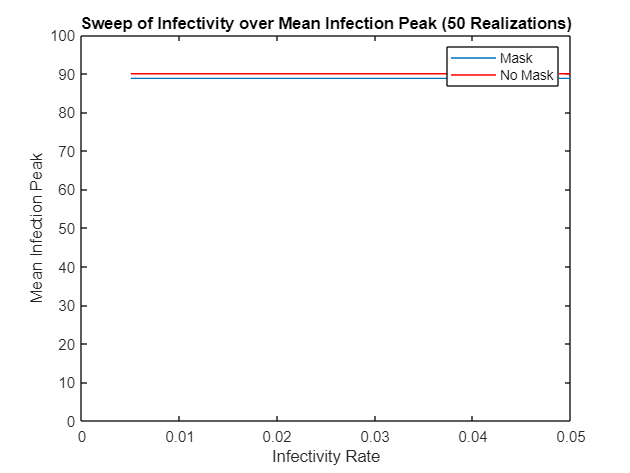

% Set infectivity rate values to sweep
infectivity_all = linspace(.005, 0.05, 100);

% Store metric (mean infection peak)
mean_infection_peak_mask = zeros(1, 100);
mean_infection_peak_no_mask = zeros(1, 100);

% Store simulation results
I_ensemble_no_mask_sweep = zeros(T_simulation, n_realizations);
I_ensemble_mask_sweep = zeros(T_simulation, n_realizations);

% run simulation for each value of infectivity rate

    for i = 1 : length(infectivity_all)
        infectivity_rate = infectivity_all(i);

        % Run a single simulation
        I1 = zeros(pop, 1);
        I1(1) = 1;
        [Sh_mask_sweep, Ih_mask_sweep, Rh_mask_sweep] = simulate_absir(masked_vulnerability_matrix, I1, T_simulation, infectivity_rate, recovery_rate);
        [Sh_no_mask_sweep, Ih_no_mask_sweep, Rh_no_mask_sweep] = simulate_absir(no_mask_matrix, I1, T_simulation, infectivity_rate, recovery_rate);

        % Summarize and store the infection history
        I_ensemble_mask_sweep(:, i) = sum(Ih_mask, 1);
        I_ensemble_no_mask_sweep(:, i) = sum(Ih_no_mask, 1);

        % Get mean
        I_mean_mask = mean(I_ensemble_mask, 2); % mask mean
        I_mean_no_mask = mean(I_ensemble_no_mask, 2); % no mask mean

        % Get mean peaks and store as metrics
        mean_infection_peak_mask(i) = max(I_mean_mask); % mask
        mean_infection_peak_no_mask(i) = max(I_mean_no_mask); % no mask
    end
[mx,my] = polyxpoly(infectivity_all, mean_infection_peak_mask, infectivity_all, mean_infection_peak_no_mask);
% Plot results
plot(infectivity_all, mean_infection_peak_mask, 'DisplayName', 'Mask'); hold on % mask
plot(mx,my,'g.', 'MarkerSize', 15, 'DisplayName', 'Masks not effective');
plot(infectivity_all, mean_infection_peak_no_mask, 'r', 'DisplayName', 'No Mask'); hold off % no mask
xlabel('Infectivity Rate')
ylabel('Mean Infection Peak')
title('Sweep of Infectivity over Mean Infection Peak (50 Realizations)')
legend()
ylim([0 100])
xlim([0 0.05])


summary = [infectivity_all; mean_infection_peak_no_mask; mean_infection_peak_mask]

summary =     0.0050    0.0055    0.0059    0.0064    0.0068    0.0073    0.0077    0.0082    0.0086    0.0091    0.0095    0.0100    0.0105    0.0109    0.0114    0.0118    0.0123    0.0127    0.0132    0.0136    0.0141    0.0145    0.0150    0.0155    0.0159    0.0164    0.0168    0.0173    0.0177    0.0182    0.0186    0.0191    0.0195    0.0200    0.0205    0.0209    0.0214    0.0218    0.0223    0.0227    0.0232    0.0236    0.0241    0.0245    0.0250    0.0255    0.0259    0.0264    0.0268    0.0273
   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.9900   89.990